# Import data from text file

Script for importing data from the following text file:

Auto-generated by MATLAB on 10-May-2024 10:15:38

## Set up the Import Options and import the data

opts = delimitedTextImportOptions("NumVariables", 6);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Name", "Team", "Position", "Height_inches_", "Weight_lbs_", "Age"];
opts.VariableTypes = ["string", "categorical", "categorical", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "Name", "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["Name", "Team", "Position"], "EmptyFieldRule", "auto");

% Import the data
mlb_players = readtable("/MATLAB Drive/S1, 2024/Week 10/mlb_players.csv", opts)

mlb_players = 1035x6 table
          Name           Team       Position       Height_inches_    Weight_lbs_     Age 
    _________________    ____    ______________    ______________    ___________    _____

    "Adam Donachie"      BAL     Catcher                 74              180        22.99
    "Paul Bako"          BAL     Catcher                 74              215        34.69
    "Ramon Hernandez"    BAL     Catcher                 72              210        30.78
    "Kevin Millar"       BAL     First Baseman           72              210        35.43
    "Chris Gomez"        BAL     First Baseman           73              188        35.71
    "Brian Roberts"      BAL     Second Baseman          69              176        29.39
    "Miguel Tejada"      BAL     Shortstop      

## Clear temporary variables

clear opts

## Activity 5: Correlation Matrix

% You first want to find the correlation between TWO (2) variables
corr(mlb_players.Height_inches_, mlb_players.Weight_lbs_, "Rows", "complete")

ans = 0.5319

% Create a correlation matrix based on columns 4 and 5. The "rows" ->
% "complete" ensures every row is accounted for in an extensive dataset.
corr_matrix = corrcoef(mlb_players{:, 4:5}, "Rows", "complete")

corr_matrix =     1.0000    0.5319
    0.5319    1.0000


% Label the x-axis for the heat map
xvalues = {'Height', 'Weight'}

xvalues = 1x2 cell array
    {'Height'}    {'Weight'}


% Label the x-axis for the heat map
yvalues = {'Height', 'Weight'}

yvalues = 1x2 cell array
    {'Height'}    {'Weight'}


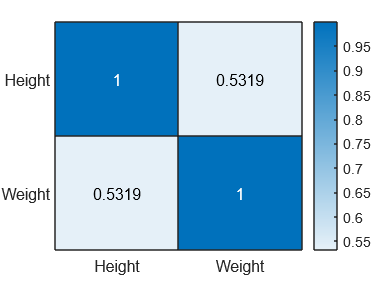

% Create a heatmap based on the corr_matrix we created
heatmap(xvalues, yvalues, corr_matrix)